clc
clear all
close all
load('Received.mat')

C = 1500; % speed in m/s
dt = 2e-4;
%looking for at which depth the signal came at first
%it will be near that depth
t = dt:dt:6.4;

header = ['Receiver at ', ' m depth'];

header = 'Receiver at  m depth'

colors = ['r', 'g', 'b', 'c', 'm', 'y','k', 'g', 'b'];

colors = 'rgbcmykgb'

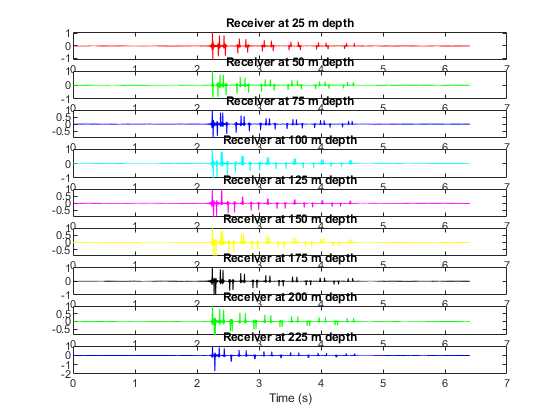

depths = [' 25 '; ' 50 '; ' 75 '; ' 100'; ' 125'; ' 150'; ' 175'; ' 200'; ' 225'];

figure(1)
for i = 1:size(RecSig,1)
    signal = RecSig(i,:);
    subplot(9,1,i)
    plot(t, signal, colors(i));
    xlabel('Time (s)')
    title(strcat('Receiver at ',depths(i,:),' m depth'))
    hold off
end

% The code is trying to find the first peak of each signal,which is the highest point in the signal. 
% It does this by first takeing the absoulute value of  the signal to make all negative values positive.
% For that pourpose we use a threshold of 0.5
% Any value diffrent of 0.5 will be handled like noise

absolute_signal = zeros(9, length(RecSig));
absolute = 0;

for i = 1:9
    
    for j = 1:length(RecSig)
        absolute = RecSig(i,j);
        if absolute > 0.5
            absolute_signal(i,j) = absolute;
            break;
        else 
            absolute_signal(i,j) = 0;
        end
    end
   

end

% Find the value different of 0 for each signal and the time when it was received
[max_signals, max_signal_index] = max(absolute_signal,[],2);

% Find estaimted depth and the time of arrival
[time,estimated_depth] = min(max_signal_index);
time = t(time)

time = 2.2444

estimated_depth = 25*estimated_depth

estimated_depth = 125

for i = 1:9
    i*25
    t(max_signal_index(i))
    
end

ans = 25

ans = 2.2472

ans = 50

ans = 2.2466

ans = 75

ans = 2.2450

ans = 100

ans = 2.2448

ans = 125

ans = 2.2444

ans = 150

ans = 2.2450

ans = 175

ans = 2.2454

ans = 200

ans = 2.2468

ans = 225

ans = 2.2484


% Assign variable names to the time of coming at different depths
t_25 = t(max_signal_index(1));
t_125 = t(max_signal_index(5));

% Calculate time difference and distance covered
Del_T = t_25 - t_125

Del_T = 0.0028

del_d = Del_T * C

del_d = 4.2000


% Use pythagorean theorem to find distance of receivers from source

syms d_125 d_25;
d_25 = d_125 + del_d;
eq1 = simplify(d_125^2 +100^2 -d_25^2)

$$eq1 = {d_{125}}^{2}-{\left(d_{125}+\frac{1182194902184625}{281474976710656}\right)}^{2}+10000$$

distance_in_x = vpa(solve(eq1==0, d_125), 4)

$$distance\_in\_x = 1188.0$$

% Defines the search grid
% X coordinates
x_coordinates = -1200:2:-800;
% Y coordinates
y_coordinate = 100:2:150;

% initialice the energy matrix
energy_values = zeros(length(x_coordinates), length(y_coordinates));
% Optimized search
% This wil help to calculate the energy using the greater values
RecSig = RecSig(:,11000:25000);
% The following loop calculates thee energy calculated per coodinate

for i = 1:length(x_coordinates)
    x = x_coordinates(i);
    for j = 1:length(y_coordinate)
        y = y_coordinate(j);
        sig = get_signal_at_a_point(RecSig,x, y);
        energy_sig = sig.^2;
        energy_val = sum(sum(energy_sig));
        energy_values(j,i) = energy_val;
    end
end

x = -1200

x = -1198

x = -1196

x = -1194

x = -1192

x = -1190

x = -1188

x = -1186

x = -1184

x = -1182

x = -1180

x = -1178

x = -1176

x = -1174

x = -1172

x = -1170

x = -1168

x = -1166

x = -1164

x = -1162

x = -1160

x = -1158

x = -1156

x = -1154

x = -1152

x = -1150

x = -1148

x = -1146

x = -1144

x = -1142

x = -1140

x = -1138

x = -1136

x = -1134

x = -1132

x = -1130

x = -1128

x = -1126

x = -1124

x = -1122

x = -1120

x = -1118

x = -1116

x = -1114

x = -1112

x = -1110

x = -1108

x = -1106

x = -1104

x = -1102

x = -1100

x = -1098

x = -1096

x = -1094

x = -1092

x = -1090

x = -1088

x = -1086

x = -1084

x = -1082

x = -1080

x = -1078

x = -1076

x = -1074

x = -1072

x = -1070

x = -1068

x = -1066

x = -1064

x = -1062

x = -1060

x = -1058

x = -1056

x = -1054

x = -1052

x = -1050

x = -1048

x = -1046

x = -1044

x = -1042

x = -1040

x = -1038

x = -1036

x = -1034

x = -1032

x = -1030

x = -1028

x = -1026

x = -1024

x = -1022

x = -1020

x = -1018

x = -1016

x = -1014

x = -1012

x = -1010

x = -1008

x = -1006

x = -1004

x = -1002

x = -1000

x = -998

x = -996

x = -994

x = -992

x = -990

x = -988

x = -986

x = -984

x = -982

x = -980

x = -978

x = -976

x = -974

x = -972

x = -970

x = -968

x = -966

x = -964

x = -962

x = -960

x = -958

x = -956

x = -954

x = -952

x = -950

x = -948

x = -946

x = -944

x = -942

x = -940

x = -938

x = -936

x = -934

x = -932

x = -930

x = -928

x = -926

x = -924

x = -922

x = -920

x = -918

x = -916

x = -914

x = -912

x = -910

x = -908

x = -906

x = -904

x = -902

x = -900

x = -898

x = -896

x = -894

x = -892

x = -890

x = -888

x = -886

x = -884

x = -882

x = -880

x = -878

x = -876

x = -874

x = -872

x = -870

x = -868

x = -866

x = -864

x = -862

x = -860

x = -858

x = -856

x = -854

x = -852

x = -850

x = -848

x = -846

x = -844

x = -842

x = -840

x = -838

x = -836

x = -834

x = -832

x = -830

x = -828

x = -826

x = -824

x = -822

x = -820

x = -818

x = -816

x = -814

x = -812

x = -810

x = -808

x = -806

x = -804

x = -802

x = -800

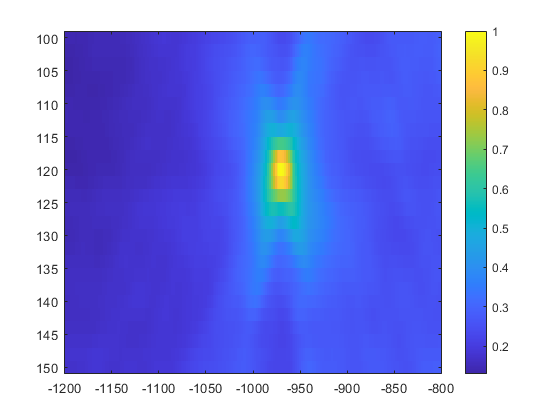

figure(2)
image(x_coordinates, y_coordinate,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

% returns the maximun value of the energy matrix
[Max,index] = Max3d(energy_values)

Max = 5.8799e-04

index =     11   116


% get the estimated depth
depth = index(1,1)*2

depth = 22

% calculates the estimated distance x
distance_x = 1250 - index(1,2)*2

distance_x = 1018

function [Max,index] = Max3d(x)
% Check if input is a 3D array
    if ndims(x) ~= 3
    error('Input must be a 3D array')
    end
    [Max,t] = max(x(:));
    [i,j,k] = ind2sub(size(x),t);
    index = [i,j,k];
end


function all_sig = get_signal_at_a_point(RecSig, destination_x, destination_y)

dt = 2e-4;
t = dt:dt:6.4;
signals = 0;

    for i = 1:9
        recv_signal = RecSig(i,:)';
        % Padd the signal to make the estimation
        reversed_signal = flip(cat(1,zeros(size(t,2)-size(recv_signal,1),1),recv_signal));
        sig = green(0, i*25, destination_x, destination_y, reversed_signal,t);
        if signals==0
            signals = sig;
        else
            signals = signals+sig;
    
        end  
    end


end


function g = green(xs, zs, x, z,signal, t)

% Inital conditions
h = 350; 
c = 1500;
dt = 2e-4;
fs = 1/dt;

% Inital conditions green function 

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);


for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end




